## Finding Signal Periodicities

The frequency domain representation of a signal allows you to observe several characteristics of the signal that are either not easy to see, or not visible at all when you look at the signal in the time domain. For instance, frequency-domain analysis becomes useful when you are looking for cyclic behavior of a signal.

**Analyzing Cyclic Behavior of the Temperature in an Office Building**

Consider a set of temperature measurements in an office building during the winter season. Measurements were taken every 30 minutes for about 16.5 weeks. Look at the time domain data with the time axis scaled to weeks. Could there be any periodic behavior on this data?

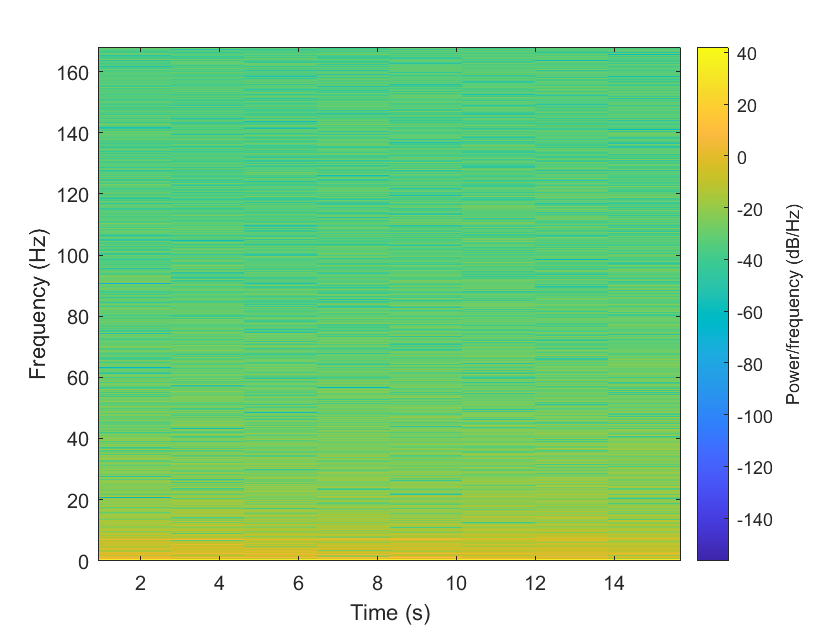

clc
clear
close all

load officetemp.mat
Fs = 1/(60*30);   % Sample rate is 1 sample every 30 minutes
t = (0:length(temp)-1)'/Fs;

figure
spectrogram(temp,[],[],[],1*7*24*2,'yaxis')

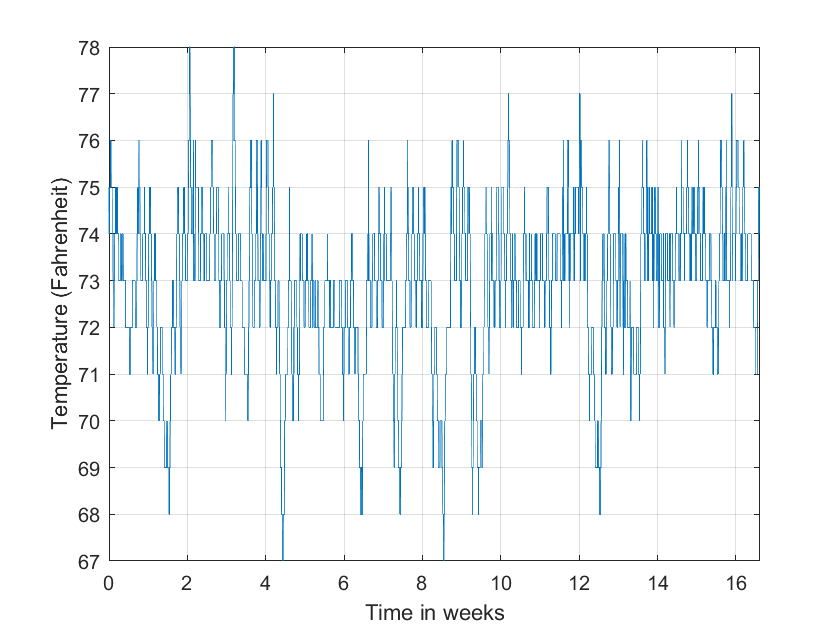


helperFrequencyAnalysisPlot2(t/(60*60*24*7),temp,...
  'Time in weeks','Temperature (Fahrenheit)')

It is almost impossible to know if there is any cyclic behavior on the office temperatures by looking at the time-domain signal. However, the cyclic behavior of the temperature becomes evident if we look at its frequency-domain representation.

Obtain the frequency-domain representation of the signal. If you plot the magnitude of the FFT output with a frequency axis scaled to cycles/week, you can see that there are two spectral lines that are clearly larger than any other frequency component. One spectral line lies at 1 cycle/week, the other one lies at 7 cycles/week. This makes sense given that the data comes from a temperature-controlled building on a 7 day calendar. The first spectral line indicates that building temperatures follow a weekly cycle with lower temperatures on the weekends and higher temperatures during the week. The second line indicates that there is also a daily cycle with lower temperatures during the night and higher temperatures during the day.

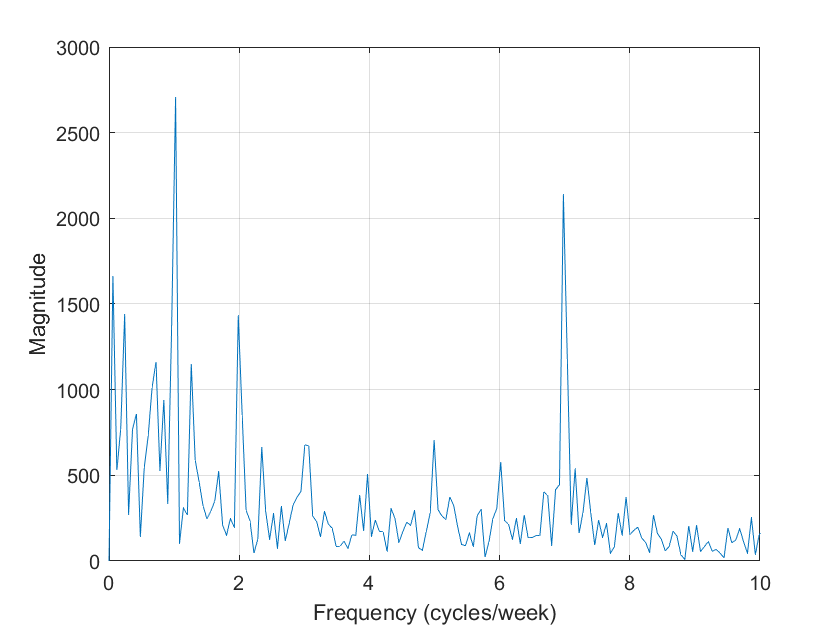

NFFT = length(temp);              % Number of FFT points
F = (0 : 1/NFFT : 1/2-1/NFFT)*Fs; % Frequency vector

TEMP = fft(temp,NFFT);            
TEMP(1) = 0; % remove the DC component for better visualization

helperFrequencyAnalysisPlot2(F*60*60*24*7,abs(TEMP(1:NFFT/2)),...
  'Frequency (cycles/week)','Magnitude',[],[],[0 10])

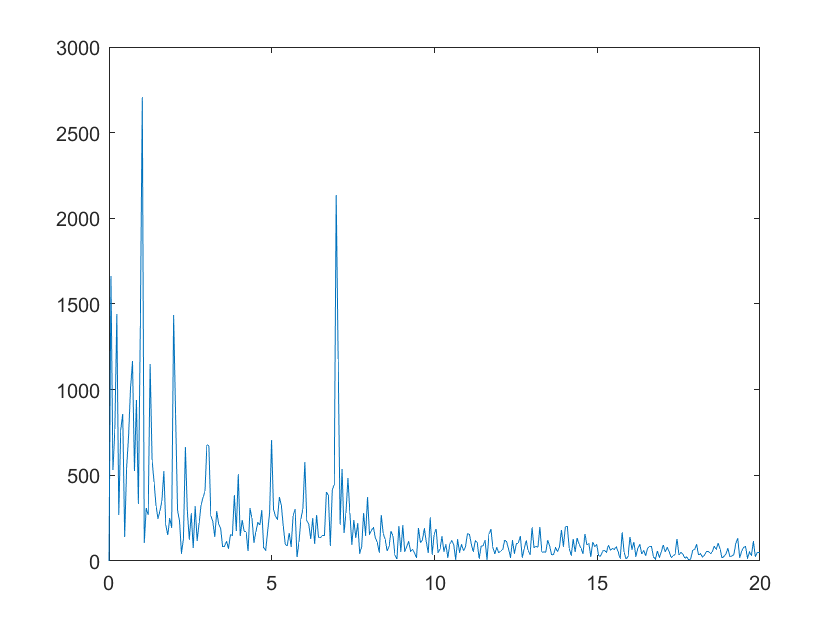

Y=fft(temp,NFFT);
Y(1)=0;
y=abs(Y(1:NFFT/2));
ff = (0 : 1/NFFT : 1/2-1/NFFT)'*(2*24*7); % Frequency vectorF = (0 : 1/NFFT : 1/2-1/NFFT)*Fs; % Frequency vector
figure
plot(ff,y);
xlim([0,20])